**colGreen function** 


$$s\left(t\right)*G\left(x,z,t,0,z_s ,0\right)=-\sum_{j=-\infty }^{\infty } \frac{\epsilon_j }{4\pi r_j }s\left(t-\frac{r_j }{c}\right)$$


$s\left(t\right)$ is the transmitter function

Ex. $s\left(t\right)=\frac{\sin \left(\pi \textrm{Bt}\right)}{\pi \textrm{Bt}}$

clear all

rho = 1000

rho = 1000

c = 1470

c = 1470


% transmitter function 
B = 500

B = 500

dt = 1/(2*B)

dt = 1.0000e-03

start = -0.05

start = -0.0500

finish = 0.05

finish = 0.0500


t = linspace(start,finish,(finish-start)/dt)

t =    -0.0500   -0.0490   -0.0480   -0.0470   -0.0460   -0.0449   -0.0439   -0.0429   -0.0419   -0.0409   -0.0399   -0.0389   -0.0379   -0.0369   -0.0359   -0.0348   -0.0338   -0.0328   -0.0318   -0.0308   -0.0298   -0.0288   -0.0278   -0.0268   -0.0258   -0.0247   -0.0237   -0.0227   -0.0217   -0.0207   -0.0197   -0.0187   -0.0177   -0.0167   -0.0157   -0.0146   -0.0136   -0.0126   -0.0116   -0.0106   -0.0096   -0.0086   -0.0076   -0.0066   -0.0056   -0.0045   -0.0035   -0.0025   -0.0015   -0.0005


s = @(t)awgn(sinc(B*t),20)

s = function_handle with value:
    @(t)awgn(sinc(B*t),20)


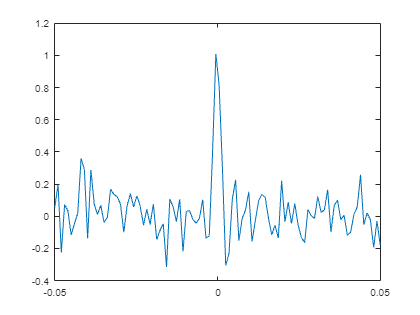


plot(t,s(t))

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% depth
h = 350;

% transmitter
x_s = 0;
z_s = 100;

% receiver 
x = 1000;
z = 120;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
start = -1;
finish = 4;

t = linspace(start,finish,(finish-start)/dt);
z_list = linspace(0, h, 10)

z_list =          0   38.8889   77.7778  116.6667  155.5556  194.4444  233.3333  272.2222  311.1111  350.0000


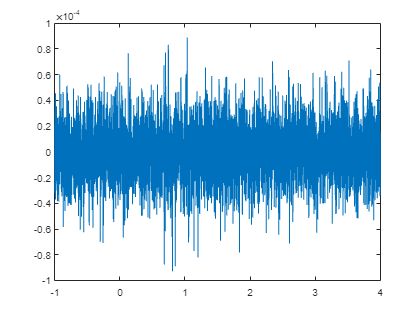

s_table = zeros(size(z_list, 1), size(t,2));

for i = 1:size(z_list,2)
    s_table(i,:) = greenFunc(x_s,z_s,x,z_list(i),h,c,s,t);
end

plot(t, s_table(end/2,:))


%% check on only one receiver 
s = flip(s_table(end/2,:))

s = 1.0e-04 *

    0.1491   -0.2500   -0.3410   -0.0338   -0.0677    0.0147    0.0976    0.5379    0.3935    0.2841   -0.1228    0.2298    0.0402    0.2273   -0.1689   -0.2723   -0.1364   -0.1801    0.3219   -0.2611    0.2024   -0.2437   -0.2099   -0.0519    0.0520   -0.1705   -0.0176    0.5079   -0.0107   -0.1838    0.2994   -0.3083    0.0969   -0.0410   -0.1161   -0.1407   -0.1484    0.0565    0.0822    0.2081   -0.1608    0.4093    0.1253   -0.1722    0.2238   -0.3598   -0.1440   -0.0914    0.1730    0.1859


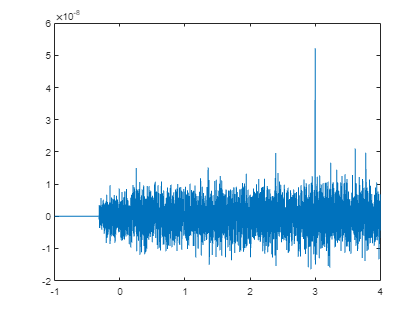

plot(t, greenFunc2(x,z_list(end/2),x_s,z_s,h,c,s,t,dt))

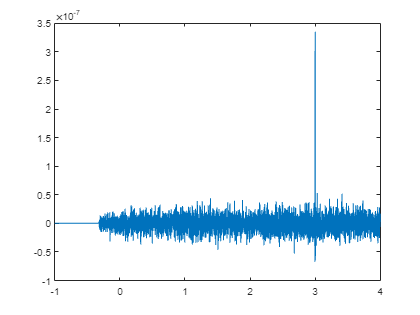

%%

out = zeros(1,size(s_table,2));
for i = 1:size(z_list,2)
    out = out + greenFunc2(x,z_list(i),x_s,z_s,h,c,flip(s_table(i,:)),t,dt);
end
plot(t,out)

Plot energy 

ds = 2

ds = 2

wx = 50

wx = 50

wz = 50

wz = 50


x_s

x_s = 0

z_s

z_s = 100

[X,Z] = meshgrid(x_s-wx/2:ds:x_s+wx/2, z_s-wz/2:ds:z_s+wz/2);
Z

Z =     75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75
    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77
    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79
    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81
    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83
    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85
    87    87    87    87    87    87    87    87    87

X

X =    -25   -23   -21   -19   -17   -15   -13   -11    -9    -7    -5    -3    -1     1     3     5     7     9    11    13    15    17    19    21    23    25
   -25   -23   -21   -19   -17   -15   -13   -11    -9    -7    -5    -3    -1     1     3     5     7     9    11    13    15    17    19    21    23    25
   -25   -23   -21   -19   -17   -15   -13   -11    -9    -7    -5    -3    -1     1     3     5     7     9    11    13    15    17    19    21    23    25
   -25   -23   -21   -19   -17   -15   -13   -11    -9    -7    -5    -3    -1     1     3     5     7     9    11    13    15    17    19    21    23    25
   -25   -23   -21   -19   -17   -15   -13   -11    -9    -7    -5    -3    -1     1     3     5     7     9    11    13    15    17    19    21    23    25
   -25   -23   -21   -19   -17   -15   -13   -11    -9    -7    -5    -3    -1     1     3     5     7     9    11    13    15    17    19    21    23    25
   -25   -23   -21   -19   -17   -15   -13   -11    -9


Energy = zeros(size(X));
for i = 1:size(Z,1)
    for j = 1:size(X,2)
        out = zeros(1,size(s_table,2));
        for k = 1:size(z_list,2)
            out = out + greenFunc2(x,z_list(k),X(1,j),Z(i,1),h,c,flip(s_table(k,:)),t,dt);
        end
        Energy(i,j) = sum(out.^2);
    end
end
Energy

Energy = 1.0e-12 *

    0.7173    0.7225    0.7272    0.7112    0.6898    0.6935    0.7145    0.7248    0.7056    0.7052    0.7080    0.7079    0.7158    0.7231    0.7372    0.7367    0.7342    0.7328    0.7365    0.7400    0.7539    0.7694    0.7611    0.7574    0.7612    0.7427
    0.7397    0.7376    0.7285    0.7355    0.7453    0.7558    0.7522    0.7546    0.7641    0.7468    0.7476    0.7622    0.7635    0.7711    0.7871    0.7837    0.7778    0.7780    0.7747    0.7939    0.7886    0.7800    0.7967    0.7945    0.7808    0.7840
    0.7198    0.7144    0.7192    0.7147    0.7193    0.7342    0.7399    0.7167    0.7082    0.7223    0.7071    0.7099    0.7392    0.7395    0.7182    0.7175    0.7225    0.7326    0.7540    0.7527    0.7678    0.7776    0.7543    0.7580    0.7748    0.7672
    0.7146    0.7111    0.7099    0.7195    0.7234    0.7184    0.7071    0.7062    0.6987    0.6998    0.7197    0.7127    0.6957    0.7147    0.7306    0.7117    0.7044    0.7171    0.7280    0.7

ds_fine = 0.01

ds_fine = 0.0100

linspace(1,size(X2,2),size(X,2))

Unrecognized function or variable 'X2'.

1:size(X,2)
[X2,Z2] = meshgrid(x_s-wx/2:ds_fine:x_s+wx/2, z_s-wz/2:ds_fine:z_s+wz/2);
outData = interp2(X, Z, Energy, X2, Z2, 'linear');
imagesc(outData);
set(gca, 'XTickLabel', X(1,:));
set(gca, 'YTickLabel', Z(:,1));
colorbar;

function s_conv = greenFunc(x_s, z_s, x, z, h, c, s, t)
    s_conv = zeros(size(t));
    n_ray = 10;
    for j = -n_ray:n_ray
        if mod(j,2) == 0
            % if even 
            r_j = sqrt((x-x_s)^2 + (z-z_s+j*h)^2);
            eps_j = 1;
        else
            % if odds
            r_j = sqrt((x-x_s)^2 + (z+z_s-(j+1)*h)^2);
            eps_j = -1;
        end
%         s_conv = s_conv - (eps_j/(4*pi*r_j))*delayseq(s(t)', r_j/c, dt)';
        s_conv = s_conv - (eps_j/(4*pi*r_j))*s(t-r_j/c);
    end
end

function s_conv = greenFunc2(x_s, z_s, x, z, h, c, s, t, dt)
    s_conv = zeros(size(t));
    n_ray = 10;
    for j = -n_ray:n_ray
        if mod(j,2) == 0
            % if even 
            r_j = sqrt((x-x_s)^2 + (z-z_s+j*h)^2);
            eps_j = 1;
        else
            % if odds
            r_j = sqrt((x-x_s)^2 + (z+z_s-(j+1)*h)^2);
            eps_j = -1;
        end
        s_conv = s_conv - (eps_j/(4*pi*r_j))*delayseq(s', r_j/c, 1/dt)';
    end
end